# ECE 334 Final Project

12/10/22

Connor Prikkel

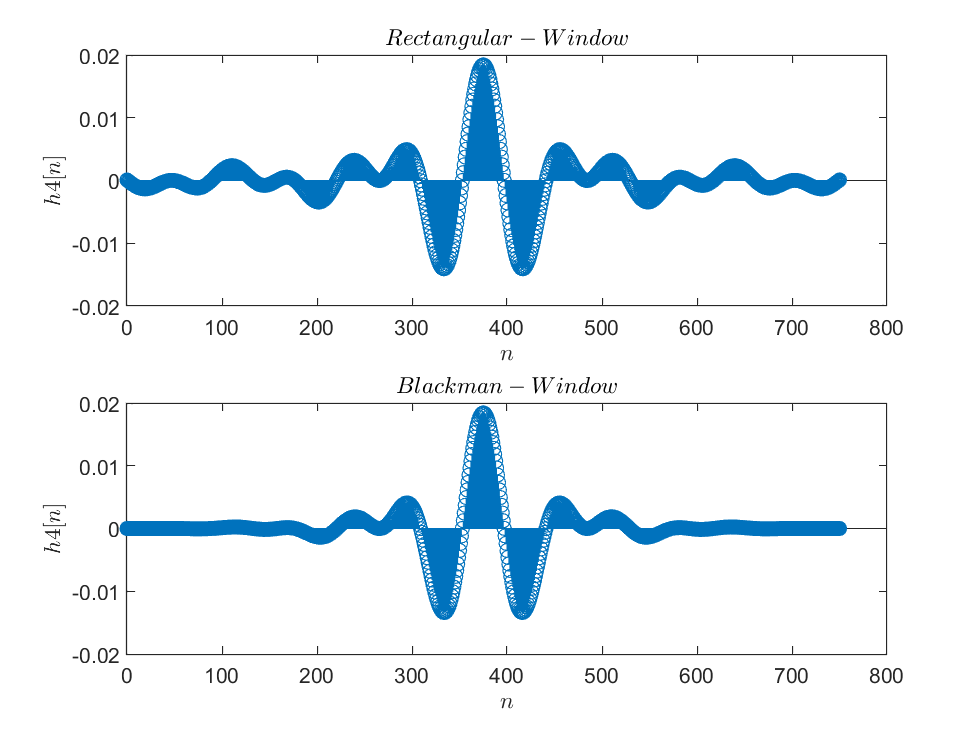

%given parameters
fs = 44100;
N = 8;
M = 751;
wl = 0;
wu = pi;

fmin = 22.5;
fmax = 22050;

%TASK 1
%create each impluse response
[h1,n] = bpw(wl, 0.00758, M, 'bart');
[h2,n] = bpw(0.00758, 0.01793, M, 'blac');
[h3,n] = bpw(0.01793, 0.04240, M, 'hamm');
[h4,n] = bpw(0.04240, 0.1003, M, 'hann');
[h5,n] = bpw(0.1003, 0.2372, M, 'rect');
[h6,n] = bpw(0.2372, 0.5610, M, 'bart');
[h7,n] = bpw(0.5610, 1.3270, M, 'blac');
[h8,n] = bpw(1.3270, wu, M, 'hamm');

%choose a gain for each filter
G1 = 15;
G2 = 20;
G3 = 8;
G4 = 30;
G5 = 2;
G6 = 5;
G7 = 25;
G8 = 1;

%multiply each impulse response computed
ht = (h1.*G1) + (h2.*G2) + (h3.*G3) + (h4.*G4) + (h5.*G5) + (h6.*G6) + (h7.*G7) + (h8.*G8);

%TASK 2
%read in audio file
[x, fs] = audioread('Undone_Clip.wav');
x = x(:, 1);
%sound(x, fs);

%convolve the audio file w/ the total impulse response
y = conv(x, ht);
%sound(conv_result, fs);

%TASK 3
%recreate h4[n] using both a rect and blac filter
[h4_rect,n] = bpw(0.04240, 0.1003, M, 'rect');
[h4_blac,n] = bpw(0.04240, 0.1003, M, 'blac');

figure(1);
subplot(2,1,1);
stem(n, h4_rect);
xlabel('$$n$$', 'Interpreter','latex');
ylabel('$$h4[n]$$', 'Interpreter', 'latex');
title('$$Rectangular-Window$$', 'Interpreter','latex');

subplot(2,1,2);
stem(n, h4_blac);
xlabel('$$n$$', 'Interpreter','latex');
ylabel('$$h4[n]$$', 'Interpreter', 'latex');
title('$$Blackman-Window$$', 'Interpreter','latex');

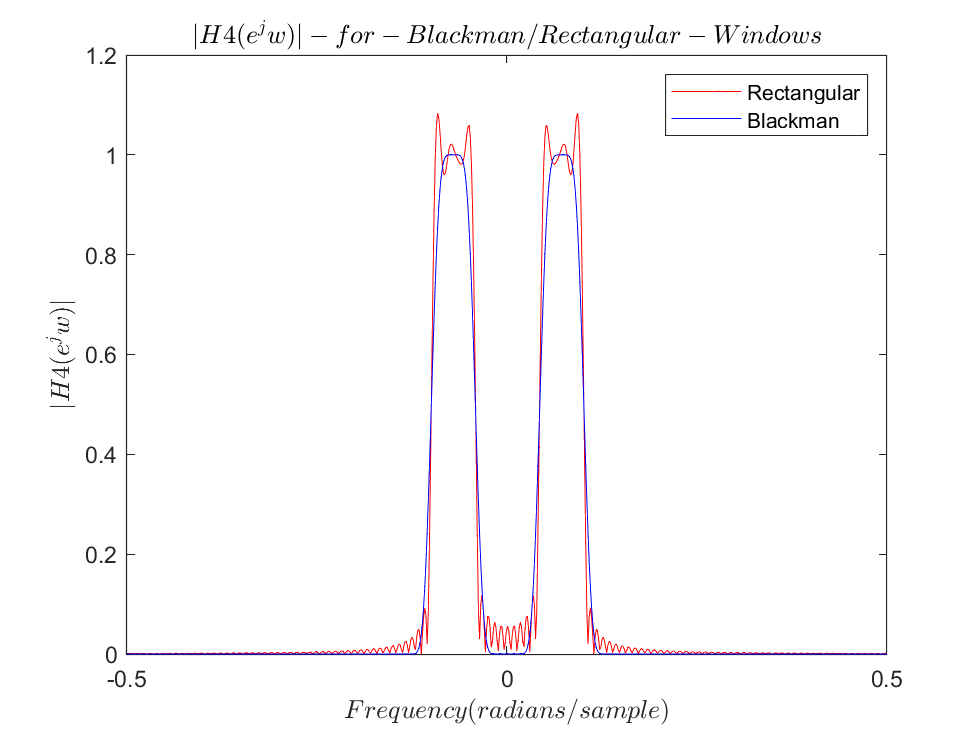


%TASK 4
%plot magnitude of freqeuncy responses on same plot
H4_rect = abs(fftshift(fft(h4_rect, 4096)));
H4_blac = abs(fftshift(fft(h4_blac, 4096)));
w = linspace(-pi, pi, 4096);

figure(2);
plot(w, H4_rect, 'r');
hold on;
plot(w, H4_blac, 'b');
axis([-0.5 0.5 0 1.2]);
xlabel('$$Frequency(radians/sample)$$', 'Interpreter','latex');
ylabel('$$|H4(e^jw)|$$', 'Interpreter', 'latex');
title('$$|H4(e^jw)|-for-Blackman/Rectangular-Windows$$', 'Interpreter','latex');
legend('Rectangular', 'Blackman');

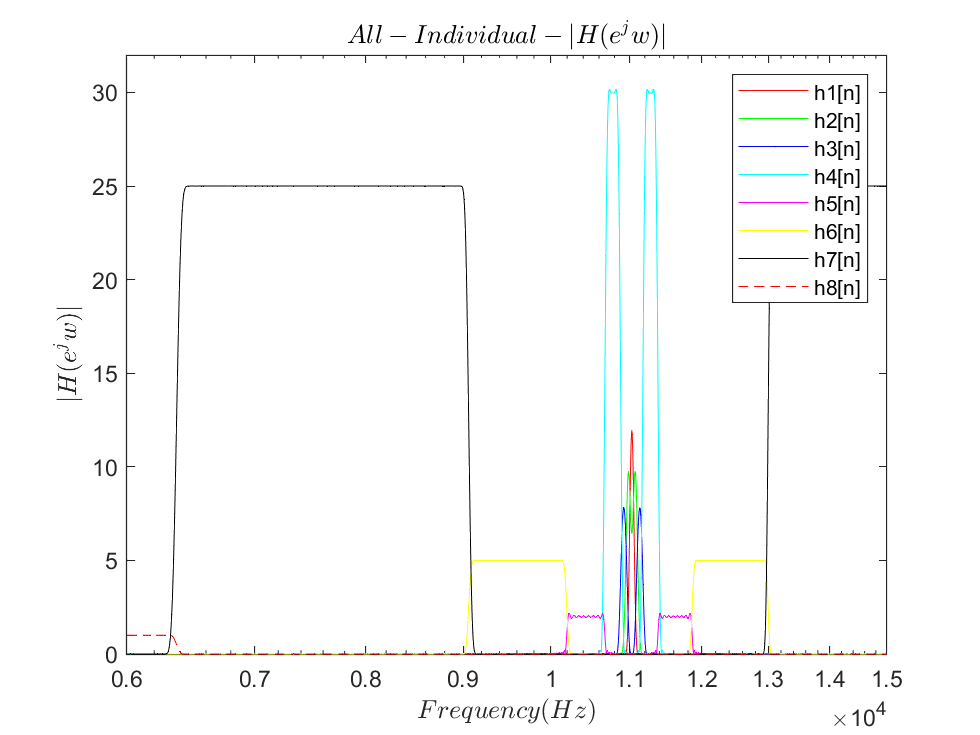


%TASK 5
%plot magnitude of freq response for each individual filter

%%%%% DIDN'T USE %%%%%%%
%re-create freq response as a function of Hz instead of digital freq
% [h1_f,n] = bpw(wl, 53.202, M, 'bart');
% [h2_f,n] = bpw(53.202, 125.846, M, 'blac');
% [h3_f,n] = bpw(125.846, 297.594, M, 'hamm');
% [h4_f,n] = bpw(297.594, 703.979, M, 'hann');
% [h5_f,n] = bpw(703.979, 1664.843, M, 'rect');
% [h6_f,n] = bpw(1664.843, 3937.509, M, 'bart');
% [h7_f,n] = bpw(3937.509, 9313.859, M, 'blac');
% [h8_f,n] = bpw(9313.859, wu, M, 'hamm');

%%%%%%%%%%%%%%%%%%%%%%%%

%using gain values selected above
h1 = h1.*G1;
h2 = h2.*G2;
h3 = h3.*G3;
h4 = h4.*G4;
h5 = h5.*G5;
h6 = h6.*G6;
h7 = h7.*G7;
h8 = h8.*G8;

H1 = abs(fftshift(fft(h1, 4096)));
H2 = abs(fftshift(fft(h2, 4096)));
H3 = abs(fftshift(fft(h3, 4096)));
H4 = abs(fftshift(fft(h4, 4096)));
H5 = abs(fftshift(fft(h5, 4096)));
H6 = abs(fftshift(fft(h6, 4096)));
H7 = abs(fftshift(fft(h7, 4096)));
H8 = abs(fftshift(fft(h8, 4096)));

%plot as a function of Hz rather than digital freq
f = linspace(0, 22050, 4096);


figure(3);
semilogx(f, H1, 'r');
hold on;
semilogx(f, H2, 'g');
hold on;
semilogx(f, H3, 'b');
hold on;
semilogx(f, H4, 'c');
hold on;
semilogx(f, H5, 'm');
hold on;
semilogx(f, H6, 'y');
hold on;
semilogx(f, H7, 'k');
hold on;
semilogx(f, H8, 'r--');

axis([6000 15000 0 32]);
xlabel('$$Frequency(Hz)$$', 'Interpreter','latex');
ylabel('$$|H(e^jw)|$$', 'Interpreter', 'latex');
title('$$All-Individual-|H(e^jw)|$$', 'Interpreter','latex');
legend('h1[n]', 'h2[n]' , 'h3[n]', 'h4[n]', 'h5[n]', 'h6[n]' , 'h7[n]', 'h8[n]');

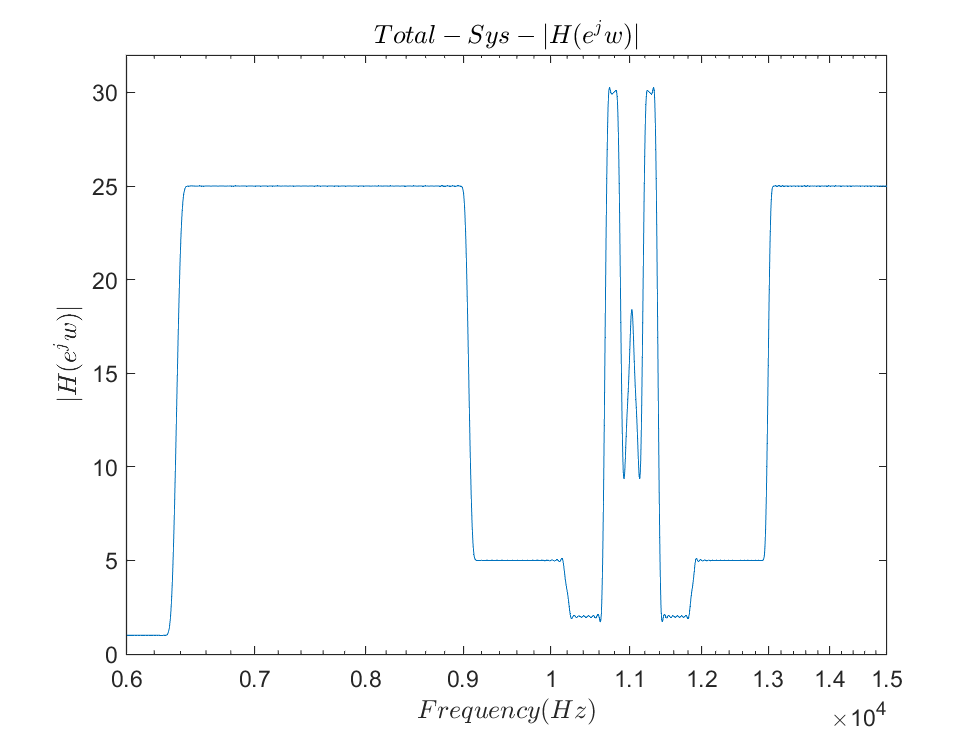


%TASK 6
%repeat previous task for total sys response

HT = abs(fftshift(fft(ht, 4096)));
figure(4);

semilogx(f, HT);
axis([6000 15000 0 32]);
xlabel('$$Frequency(Hz)$$', 'Interpreter','latex');
ylabel('$$|H(e^jw)|$$', 'Interpreter', 'latex');
title('$$Total-Sys-|H(e^jw)|$$', 'Interpreter','latex');

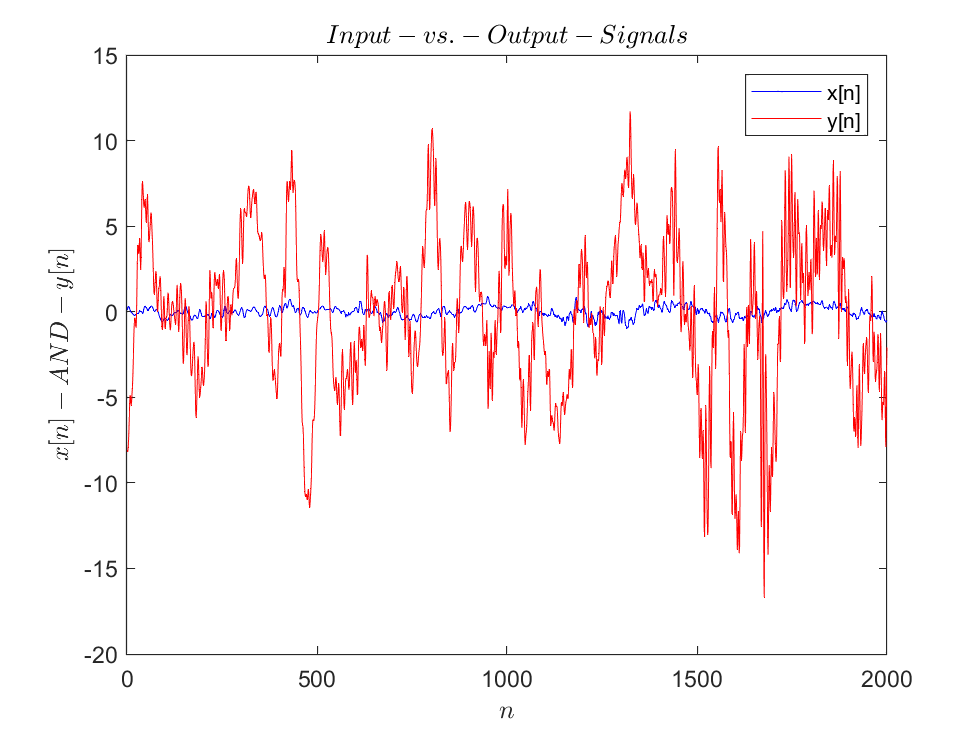


%TASK 7
%plot 2000 samples of input and output sequence

figure(5);

plot(x(1001:3000), 'b');
hold on;
plot(y(1001:3000), 'r');

xlabel('$$n$$', 'Interpreter','latex');
ylabel('$$x[n]-AND-y[n]$$', 'Interpreter', 'latex');
title('$$Input-vs.-Output-Signals$$', 'Interpreter','latex');
legend('x[n]', 'y[n]');

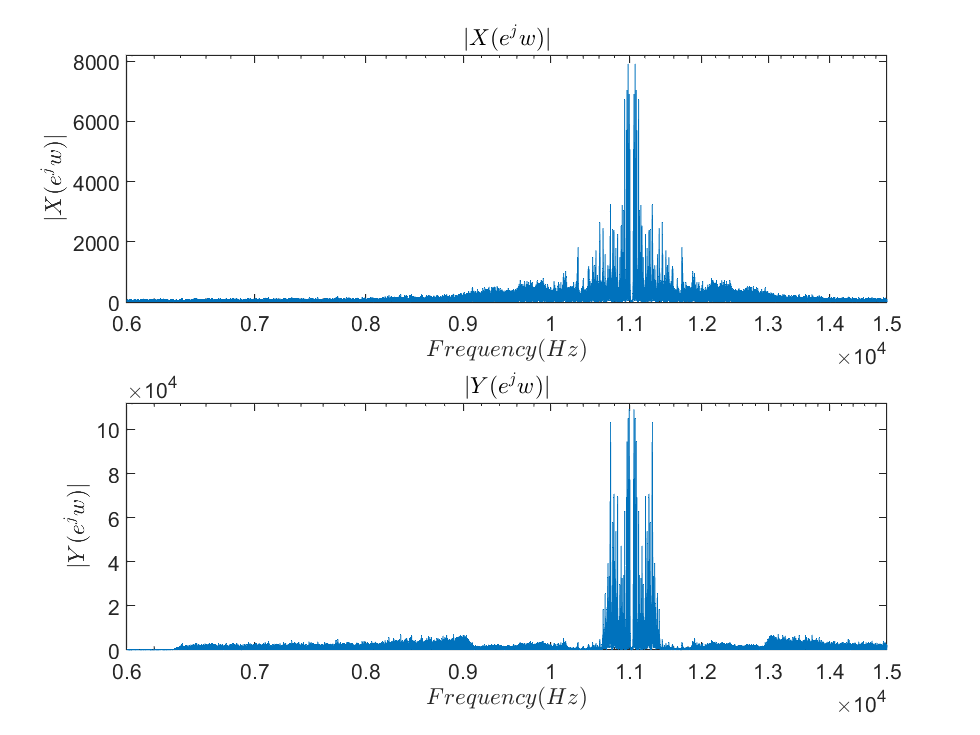


%TASK 8
%plot freq spectrum of input and output

%do not specify N for the fft
Y = abs(fftshift(fft(y)));
X = abs(fftshift(fft(x)));

%transpose X and Y to fix plotting issue
X = X.';
Y = Y.';

%plot as a function of Hz- match # of samples
f2_X = linspace(0, 22050, 537146);
f2_Y = linspace(0, 22050, 537896);

figure(6);

subplot(2,1,1);
semilogx(f2_X, X);
axis([6000 15000 0 8200]);
xlabel('$$Frequency(Hz)$$', 'Interpreter','latex');
ylabel('$$|X(e^jw)|$$', 'Interpreter', 'latex');
title('$$|X(e^jw)|$$', 'Interpreter','latex');

subplot(2,1,2);
semilogx(f2_Y, Y);
axis([6000 15000 0 112000]);
xlabel('$$Frequency(Hz)$$', 'Interpreter','latex');
ylabel('$$|Y(e^jw)|$$', 'Interpreter', 'latex');
title('$$|Y(e^jw)|$$', 'Interpreter','latex');

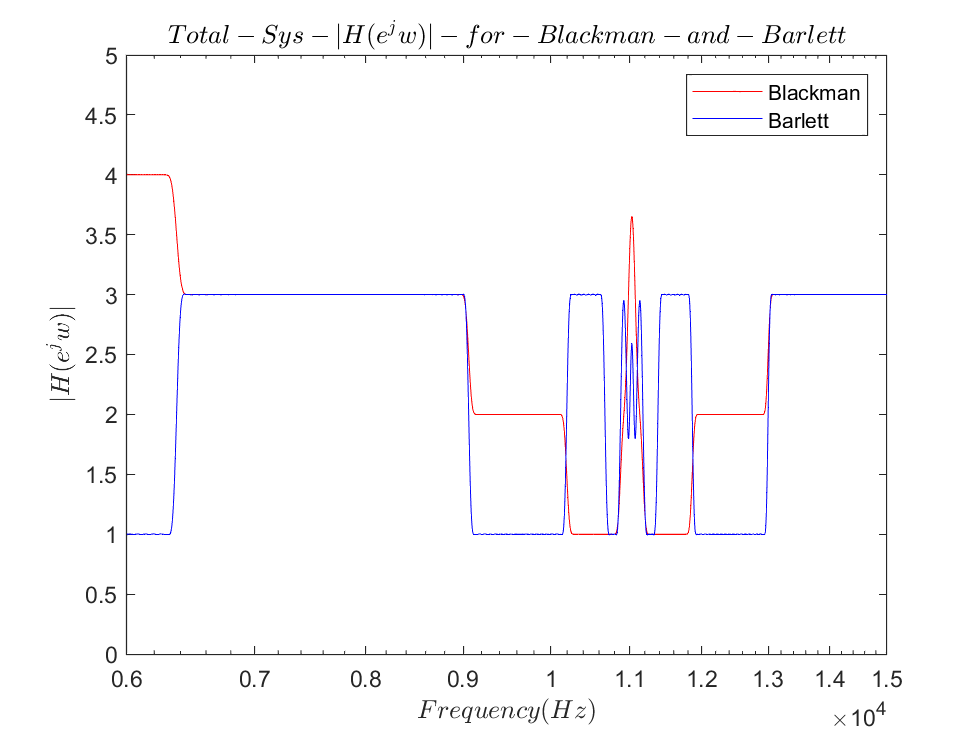


%TASK 9
%recreate equalizer h[n] w/ Blackman Window
[h1_blac,n] = bpw(wl, 0.00758, M, 'blac');
[h2_blac,n] = bpw(0.00758, 0.01793, M, 'blac');
[h3_blac,n] = bpw(0.01793, 0.04240, M, 'blac');
[h4_blac,n] = bpw(0.04240, 0.1003, M, 'blac');
[h5_blac,n] = bpw(0.1003, 0.2372, M, 'blac');
[h6_blac,n] = bpw(0.2372, 0.5610, M, 'blac');
[h7_blac,n] = bpw(0.5610, 1.3270, M, 'blac');
[h8_blac,n] = bpw(1.3270, wu, M, 'blac');

%use given gains
G1 = 4;
G2 = 3;
G3 = 2;
G4 = 1;
G5 = 1;
G6 = 2;
G7 = 3;
G8 = 4;

%multiply each impulse response computed
ht_blac = (h1_blac.*G1) + (h2_blac.*G2) + (h3_blac.*G3) + (h4_blac.*G4) + (h5_blac.*G5) + (h6_blac.*G6) + (h7_blac.*G7) + (h8_blac.*G8);

%recreate equalizer h[n] w/ Barlett Window
[h1_bart,n] = bpw(wl, 0.00758, M, 'bart');
[h2_bart,n] = bpw(0.00758, 0.01793, M, 'bart');
[h3_bart,n] = bpw(0.01793, 0.04240, M, 'bart');
[h4_bart,n] = bpw(0.04240, 0.1003, M, 'bart');
[h5_bart,n] = bpw(0.1003, 0.2372, M, 'bart');
[h6_bart,n] = bpw(0.2372, 0.5610, M, 'bart');
[h7_bart,n] = bpw(0.5610, 1.3270, M, 'bart');
[h8_bart,n] = bpw(1.3270, wu, M, 'bart');

%use given gains
G1 = 3;
G2 = 1;
G3 = 3;
G4 = 1;
G5 = 3;
G6 = 1;
G7 = 3;
G8 = 1;

%multiply each impulse response computed
ht_bart = (h1_bart.*G1) + (h2_bart.*G2) + (h3_bart.*G3) + (h4_bart.*G4) + (h5_bart.*G5) + (h6_bart.*G6) + (h7_bart.*G7) + (h8_bart.*G8);

%Plot total magnitude response of both equalizers
HT_blac = abs(fftshift(fft(ht_blac, 4096)));
HT_bart = abs(fftshift(fft(ht_bart, 4096)));

figure(7);

semilogx(f, HT_blac, 'r');
hold on;
semilogx(f, HT_bart, 'b');

axis([6000 15000 0 5]);
xlabel('$$Frequency(Hz)$$', 'Interpreter','latex');
ylabel('$$|H(e^jw)|$$', 'Interpreter', 'latex');
title('$$Total-Sys-|H(e^jw)|-for-Blackman-and-Barlett$$', 'Interpreter','latex');
legend('Blackman', 'Barlett');

function [h,n] = bpw(wl, wu, len, win)
% [h] = bpw(wl, wu, len, win);
%
% Creates a causal FIR bandpass impulse response using the windowing method 
%
% wl    Lower Cutoff (Radians): wl = [0,pi]
% wu    Upper Cutoff (Radians): wh = [0,pi], wh>wl
% len   Length of h  (should be odd)
% win   'bart', 'blac', 'hamm' 'hann' or 'rect' 
%        ==> (Bartlett, Blackman, Hamming, Hanning, Rectangular)
%
% h     Created Impulse Response
% n     Causal time index vector from [0:len-1];
% 
%
% Author: Bradley M. Ratliff, Ph.D.
% University of Dayton
% 4/22/2016

%If length is even, make it odd.
if mod(len,2) == 0
   len = len + 1;
end

%Create n vector
M = len-1;
n = [-M/2:M/2];
n2 = n+M/2;

%Create Impulse Response Using Rectangular Window
h = (wu/pi)*sinc((wu*n)/pi) - (wl/pi)*sinc((wl*n)/pi);

%Apply Appropriate Window.
if win ==     'bart'
   wn = 0.54 - 0.46*cos((2*pi*n2)/M);
elseif win == 'blac'
   wn = 0.42 - 0.5*cos(2*pi*n2/M) + 0.08*cos(4*pi*n2/M);   
elseif win == 'hamm'
   wn = 0.54 - 0.46*cos((2*pi*n2)/M);
elseif win == 'hann'
   wn = 0.5 - 0.5*cos((2*pi*n2)/M);
elseif win == 'rect'
   wn = 0*n2+1;
else
   disp('Not a valid window type! ==> Rect Window Used.');
   wn = 0*n2+1;
end
h = h.*wn;
n = n2;
end